% define sampling parameters
f1 = 470*1e3;
f2 = 600*1e3;
f = [f1,f2]

f =       470000      600000


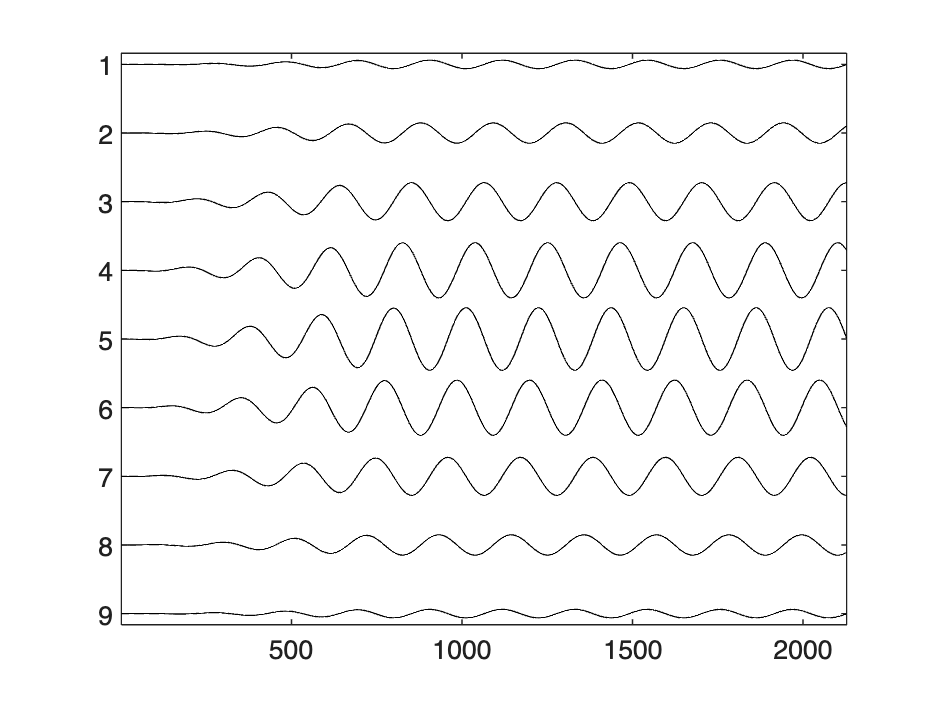

T1 = 1/f1;
Fs = 100e6;
dt = 1/Fs;
t_array = 0:dt:10*T1;

% define amplitude and phase
amp = getWin(9, 'Gaussian');

phase = linspace(0, 2*pi, 9).';

% create signals and plot

cw_signal_1 = createCWSignals(t_array, f1, amp, phase);
cw_signal_2 = createCWSignals(t_array_2, f2, amp, phase);

cw_signal = createCWSignals(t_array, f(1), amp, phase);
for i = 2:length(f)
    cw_signal = cw_signal + createCWSignals(t_array, f(i), amp, phase);
end



stackedPlot(cw_signal_1);

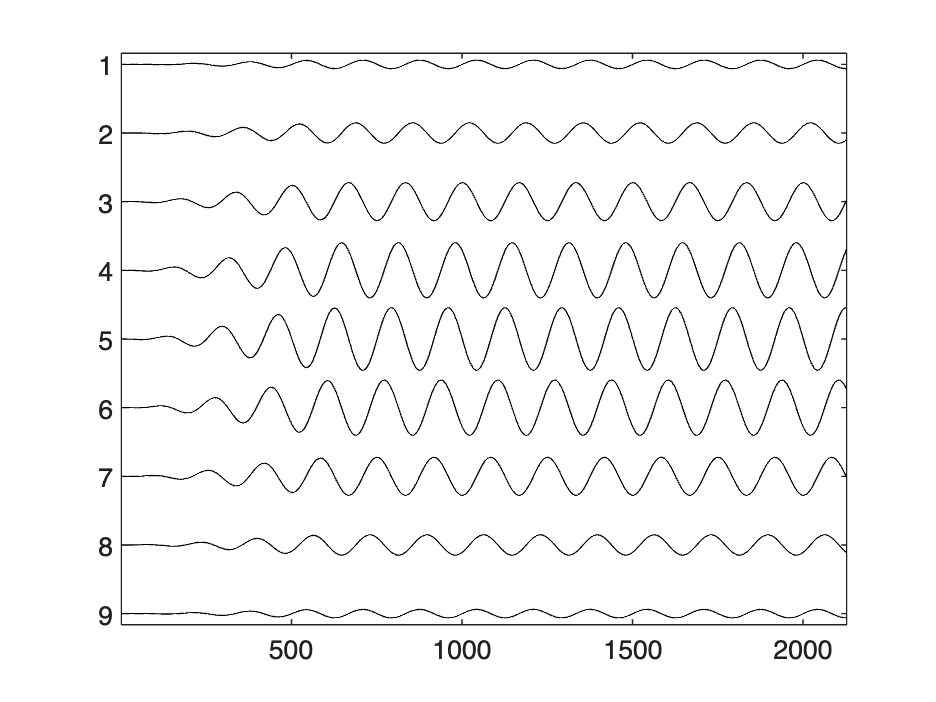

stackedPlot(cw_signal_2);

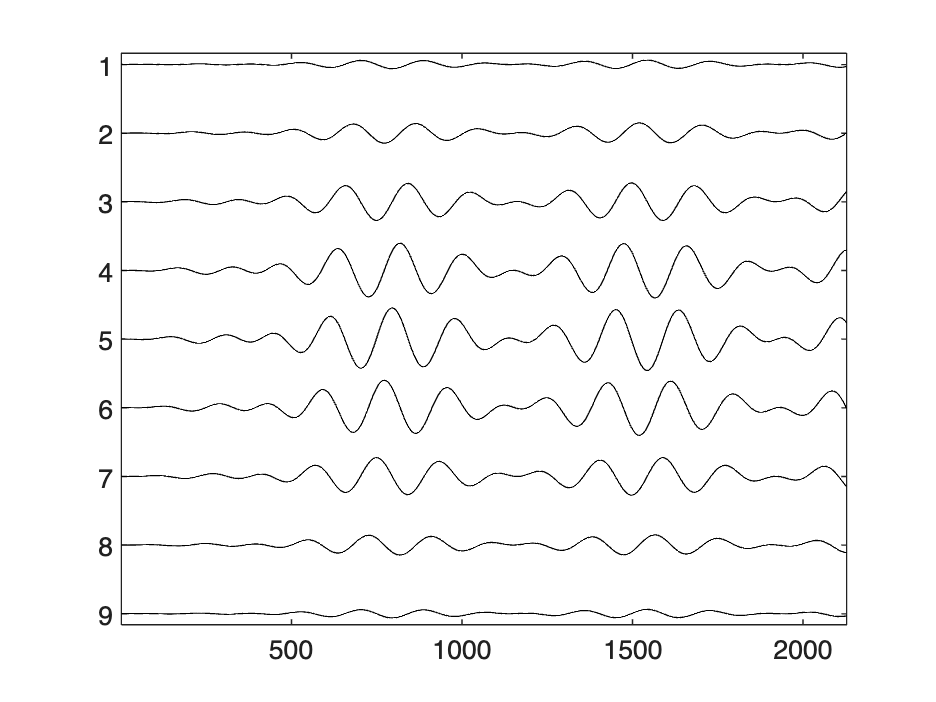

stackedPlot(cw_signal);